# Scene simulator

Here you can play with the different setups of the camera and the world. 

Observe how the projections change using the sliders below.

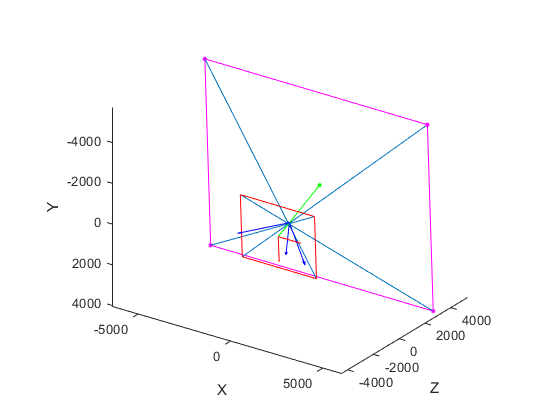

u0 = 50;
v0 = 285;
focalDistance =874;
skewAngle =-88;
tx = 44;
ty = -64;
tz = 0.1437;
rx = -68;
ry = -19;
rz = 41;

figure(), hold on;
xlabel('X');
ylabel('Z');
zlabel('Y');
set(gca,'ZDir','reverse');
axis equal;

%patch([0; 10; 10; 0], [0; 0; 10; 10], [0; 0; 10; 10], 'b');
drawcamera(u0, v0, skewAngle, 4032, 3024, focalDistance,tx,ty,tz,rx,ry,rz);

view([35 25]);

function drawcamera(u0,v0,theta,width,height,f,tx,ty,tz,rx,ry,rz)
    
    rotx = @(t) [   1       0        0;
                    0     cosd(t) -sind(t);
                    0     sind(t)  cosd(t)];
    roty = @(t) [ cosd(t)   0      sind(t);
                    0       1        0; 
                 -sind(t)   0      cosd(t)];
    rotz = @(t) [cosd(t) -sind(t)    0;
                 sind(t)  cosd(t)    0; 
                    0       0        1];

    
    shear = [1   cosd(theta)  0;
           0        1       0;
           0        0       1];
    % print image
    sw = shear * [u0 - width/2; v0 - height/2; -f];
    se = shear * [u0 + width/2; v0 - height/2; -f];
    ne = shear * [u0 + width/2; v0 + height/2; -f];
    nw = shear * [u0 - width/2; v0 + height/2; -f];
    vertices = [sw se ne nw sw];
    plot3(vertices(1,:), vertices(3,:), vertices(2,:), 'r');
    
    % print image reference system
    p = [u0,v0,-f];
    arrow_size = [10  0 0;
                   0 10 0] * width/30;
    principal = [p; p];
    arrows = principal + arrow_size;
    arrows = (shear * arrows')';
    
    diff = arrows - principal;
    quiver3(principal(:,1),principal(:,3),principal(:,2),diff(:,1),diff(:,3),diff(:,2),'r');
    
    % print center point
    C = [0,0,0];
    plot3(C(1), C(3), C(2), '.b', 'MarkerSize',10);
    
    % print frustum
    proj = 3*f;
    projs = [];
    for vert=vertices
        line([vert(1) C(1)], [vert(3) C(3)], [vert(2) C(2)]);
        mx = (vert(1) - C(1))/(vert(3) - C(3));
        my = (vert(2) - C(2))/(vert(3) - C(3));
        
        proj_vert = [mx*proj + C(1); my*proj + C(2); C(3) + proj];
        plot3(proj_vert(1), proj_vert(3), proj_vert(2), '.m', 'MarkerSize',10);
        line([proj_vert(1) C(1)], [proj_vert(3) C(3)], [proj_vert(2) C(2)]);
        projs = [projs proj_vert];
    end
    plot3(projs(1,:), projs(3,:), projs(2,:), 'm');
    
    % print optic axis
    line([p(1) C(1)], [p(3) C(3)], [p(2) C(2)],'Color','green');
    mx = (p(1) - C(1))/(p(3) - C(3));
    my = (p(2) - C(2))/(p(3) - C(3));
    
    proj_vert = [mx*proj + C(1); my*proj + C(2); C(3) + proj];
    plot3(proj_vert(1), proj_vert(3), proj_vert(2), '.g', 'MarkerSize',10);
    line([proj_vert(1) C(1)], [proj_vert(3) C(3)], [proj_vert(2) C(2)],'Color','green');
    
    % print scene reference system
    R = rotx(rx) * roty(ry) * rotz(rz);
    t = [tx,ty,tz];
    arrow_size = [20  0  0;
                   0 20  0;
                   0  0 20] * width/30;
    arrows = (R * arrow_size')' + t;
    center = [C; C; C] + t;
    
    diff = arrows - center;
    quiver3(center(:,1),center(:,3),center(:,2),diff(:,1),diff(:,3),diff(:,2),'b');
end